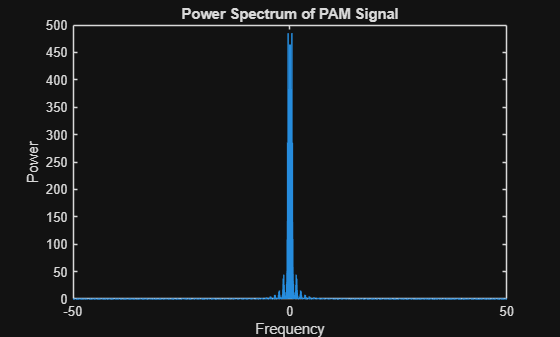

clc;
clear;
close all;

%% ----------------------------------
% PARAMETERS
%% ----------------------------------
N = 1000;        % number of symbols
M = 2;           % 2-PAM
Fs = 100;        % sampling frequency
Tb = 1;          
t = 0:1/Fs:Tb-1/Fs;

SNR_dB = 15;

%% ----------------------------------
% 1. Generate 2-PAM Signal
%% ----------------------------------
bits = randi([0 1], 1, N);
symbols = 2*bits - 1;

tx = kron(symbols, ones(1,length(t)));

%% ----------------------------------
% 2. Power Spectrum of PAM Signal
%% ----------------------------------
Nfft = length(tx);
PSD = abs(fftshift(fft(tx))).^2 / Nfft;
f = linspace(-Fs/2, Fs/2, Nfft);

figure;
plot(f, PSD);
title('Power Spectrum of PAM Signal');
xlabel('Frequency'); ylabel('Power');

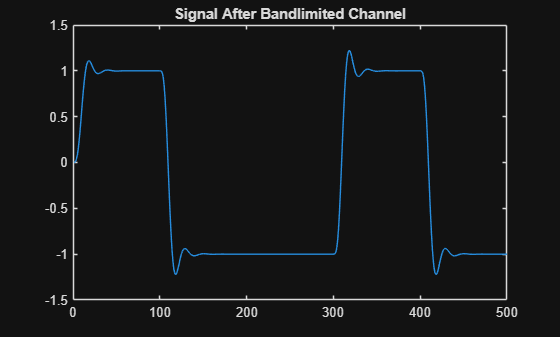


%% ----------------------------------
% 3. Bandlimited Channel (Lowpass Filter)
%% ----------------------------------
fc = 5; % cutoff frequency
[b, a] = butter(4, fc/(Fs/2), 'low');

rx_channel = filter(b, a, tx);

figure;
plot(rx_channel(1:500));
title('Signal After Bandlimited Channel');

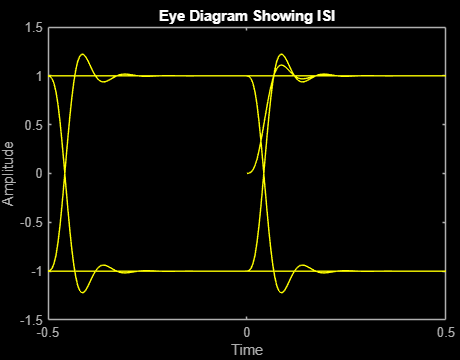


%% ----------------------------------
% 4. Intersymbol Interference (ISI)
%% ----------------------------------
% Eye Diagram visualization
figure;
eyediagram(rx_channel, 2*length(t));
title('Eye Diagram Showing ISI');

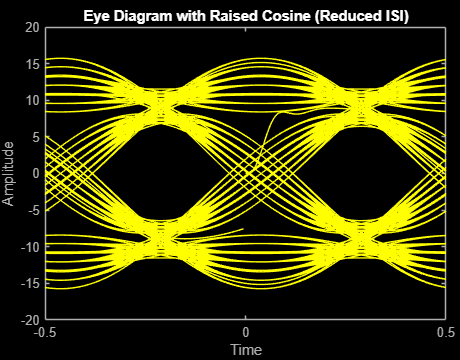


%% ----------------------------------
% 5. Zero ISI using Raised Cosine Filter
%% ----------------------------------
rolloff = 0.25;
span = 6;

rc_filter = rcosdesign(rolloff, span, Fs, 'normal');

tx_rc = conv(tx, rc_filter, 'same');

rx_rc = filter(b, a, tx_rc);

figure;
eyediagram(rx_rc, 2*length(t));
title('Eye Diagram with Raised Cosine (Reduced ISI)');

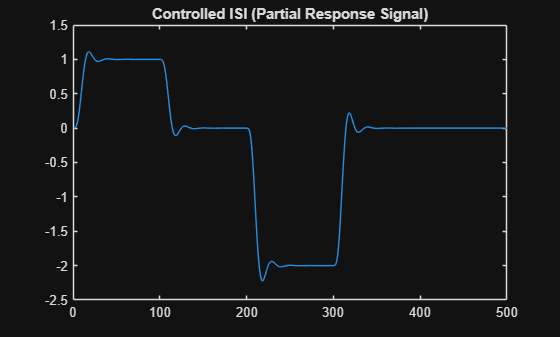


%% ----------------------------------
% 6. Controlled ISI (Partial Response)
%% ----------------------------------
% Duobinary filter
h_pr = [1 1];

tx_pr = conv(symbols, h_pr);
tx_pr_up = kron(tx_pr, ones(1,length(t)));

rx_pr = filter(b, a, tx_pr_up);

figure;
plot(rx_pr(1:500));
title('Controlled ISI (Partial Response Signal)');

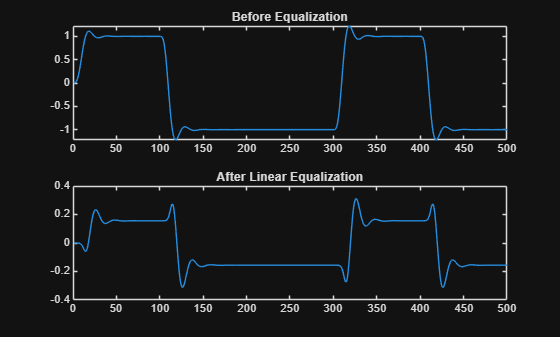


%% ----------------------------------
% 7. Linear Equalizer (Zero-Forcing)
%% ----------------------------------
% Simple inverse filtering
eq = fir1(20, fc/(Fs/2), 'high'); % approximate inverse

rx_eq = filter(eq, 1, rx_channel);

figure;
subplot(2,1,1); plot(rx_channel(1:500)); title('Before Equalization');
subplot(2,1,2); plot(rx_eq(1:500)); title('After Linear Equalization');

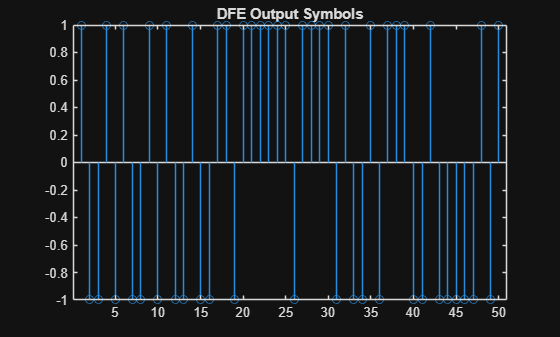


%% ----------------------------------
% 8. Nonlinear Equalizer (Decision Feedback)
%% ----------------------------------
% Simple DFE implementation
dfe_out = zeros(1, length(symbols));
prev = 0;

for i = 1:length(symbols)
    sample = rx_channel(i*length(t));
    
    % subtract previous ISI estimate
    sample_corr = sample - 0.5*prev;
    
    % decision
    if sample_corr > 0
        dfe_out(i) = 1;
    else
        dfe_out(i) = -1;
    end
    
    prev = dfe_out(i);
end

figure;
stem(dfe_out(1:50));
title('DFE Output Symbols');